# HW4 Gabe Colangelo

clear
close all
warning off
clc

% Symbolic State and Input Vectors
x_sym   = sym('x',[6,1],'real');
u_sym   = sym('u',[3,1],'real');

% Numeric System Parameters
m1      = 0.5;
L1      = 0.5;
m2      = 0.75;
L2      = 0.75;
M       = 1.5;
g       = 9.81;

## Problem 1 - Discretize Linearized Model

% Equilibrium States
xe      = [0.1, deg2rad(60), deg2rad(45),  0, 0, 0 ]';

% Solve for Equilibrium Input
fsol_opt= optimset('Display','off');
f_xe    = @(u)DIPC([],xe, u, m1, m2, M, L1, L2, g);
ue      = fsolve(f_xe,[0 0 0]',fsol_opt);

% Non-linear System
f       = DIPC([],x_sym, u_sym, m1, m2, M, L1, L2, g);
out     = x_sym(1:3);

% Equilibrium output
ye      = double(subs(out,x_sym,xe));

% Jacobian Matrices/ Linearized Model about Equilibrium Pair
A       = double(subs(jacobian(f,x_sym),[x_sym;u_sym],[xe;ue]));
B       = double(subs(jacobian(f,u_sym),[x_sym;u_sym],[xe;ue]));
C       = double(jacobian(out,x_sym));
D       = double(jacobian(out,u_sym));

% Step Size
h       = .01;

disp('The discretized linearized model about the equilibrium pair is')

The discretized linearized model about the equilibrium pair is



$$\delta x[k+1] = \Phi \delta x[k] + \Gamma u[k]
\\
\delta y[k] = C \delta x[k] + D u[k]$$


% Discretize Linearized System Using Zero Order Hold
phi     = expm(A*h)

phi =     1.0000   -0.0000   -0.0001    0.0100   -0.0000   -0.0000
         0    1.0011   -0.0009         0    0.0100   -0.0000
         0   -0.0007    1.0011         0   -0.0000    0.0100
         0   -0.0053   -0.0113    1.0000   -0.0000   -0.0001
         0    0.2252   -0.1782         0    1.0011   -0.0009
         0   -0.1400    0.2179         0   -0.0007    1.0011


gamma   = integral(@(neta) expm(A*neta),0, h,'ArrayValued', true)*B

gamma =     0.0000   -0.0000   -0.0000
   -0.0000    0.0004   -0.0002
   -0.0000   -0.0002    0.0003
    0.0043   -0.0017   -0.0029
   -0.0017    0.0735   -0.0457
   -0.0029   -0.0457    0.0558


C

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


D

D =      0     0     0
     0     0     0
     0     0     0


## Problem 2 - Unconstrained Augmented MPC

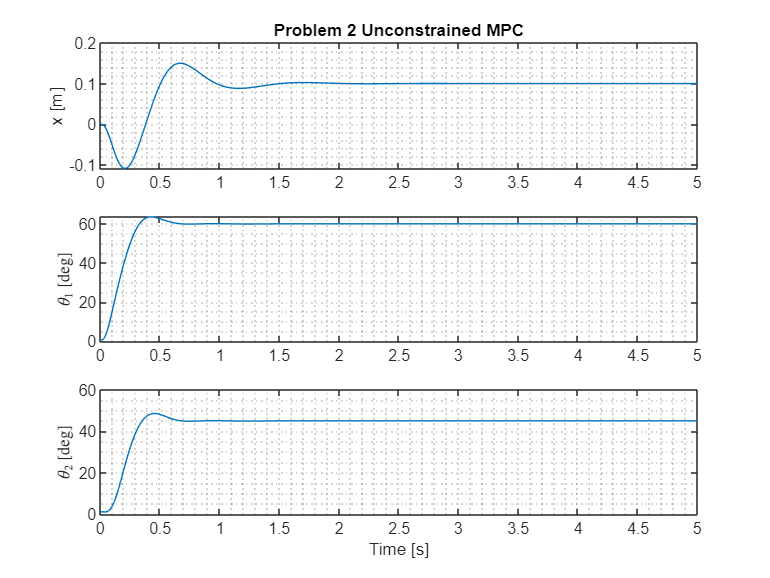

% Dimensions
[p,n] = size(C);
[~,m] = size(gamma);

% Predicition Horizon
Np      = 50;

% Weighting Matrices
Q       = 10*eye(Np*p);    % State Weight
R       = .1*eye(Np*m);    % Input Weight

% Reference Vector
rp      = kron(ones(Np,1),C*xe);

% Augmented Plant Model: state vector is length of number of states + outputs
phi_a   = [phi, zeros(n,p); C*phi, eye(p)];
gamma_a = [gamma;C*gamma];
C_a     = [zeros(p,n), eye(p)];

% Initialize W
[row, col] = size(C_a*phi_a);
W          = zeros(Np*row,col);
count      = 1;
i          = 1;

% Compute W
while count <= Np
    W(i:i+2,:) = C_a*phi_a^count;
    count      = count + 1;
    i          = i + 3;
end

% Compute Z
Z           = zeros(Np*p, Np*m);
Z(1:p,1:m)  = C_a*gamma_a;
temp        = C_a*gamma_a;

for i = 1:Np-1
    temp = [C_a*phi_a^i*gamma_a temp];
    Z(i*p+1:(i+1)*p,1:size(temp,2)) = temp;
end

% Sim Time
time        = 0:h:5;

% ODE45 solver options
options     = odeset('AbsTol',1e-8,'RelTol',1e-8);

% State IC  [m, rad, rad, m/s, rad/s, rad/s]
x0          = [0 .01 .02 0 0 0]';  

% Initialize Output and Input matrices
Y           = zeros(p,length(time));
U           = zeros(m,length(time));
X           = zeros(n,length(time));

Y(:,1)      = C*x0;
X(:,1)      = x0;

% Simulate with Unconstrained MPC Controller    
for i = 1:length(time)-1

    % Plant Dynamics
    [~, X_out]  = ode45(@(t,x) DIPC(t, x, U(:,i), m1, m2, M, L1, L2, g),[0 h],X(:,i), options);
    X(:,i+1)    = X_out(end,:)';
    Y(:,i+1)    = C*X(:,i+1);

    % Augmented state vector - [dx,y]
    xa          = [X(:,i+1) - X(:,i); Y(:,i+1)];

    % Control Action
    dU          = inv(R + Z'*Q*Z)*Z'*Q*(rp - W*xa);
    U(:,i+1)    = U(:,i) + dU(1:3);
end

figure
subplot(311)
plot(time,X(1,:))
title('Problem 2 Unconstrained MPC')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

## Problem 3 - Constrained Augmented MPC

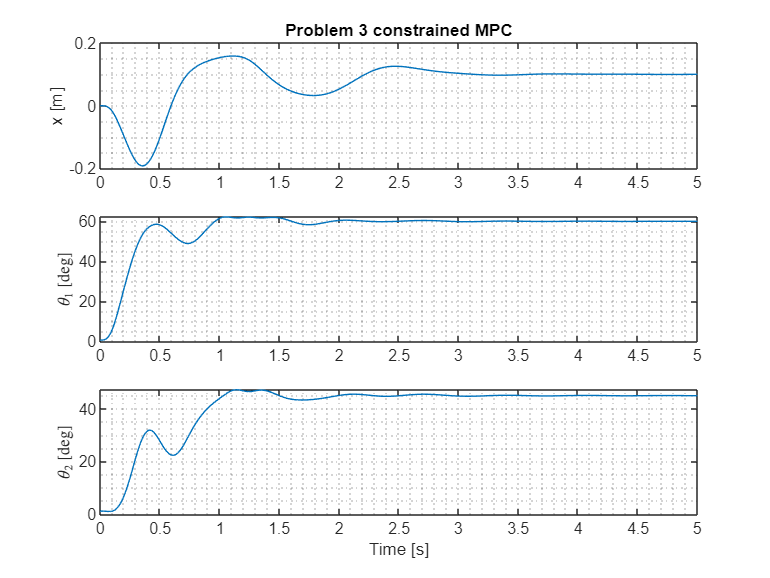

% Ouput Constraints
Ymax        = kron(ones(Np,1),[0.15 deg2rad(62), deg2rad(47)]');
Ymin        = -Ymax;

% Input Constraints: Constrain magnitude of first component of dU
% Ouput Constraints
Umax        = [5 15 15]';
Umin        = -Umax;

% Gradient of constraints
Dg          = [-eye(m), zeros(m,(Np - 1)*m); eye(m) zeros(m,(Np - 1)*m);-Z;Z];

% Initialize Output and Input matrices
Y           = zeros(p,length(time));
U           = zeros(m,length(time));
X           = zeros(n,length(time));

Y(:,1)      = C*x0;
X(:,1)      = x0;

dU          = zeros(m*Np,1);
mu          = zeros(length(Dg),1);

% Optimization Parameters
alpha       = .05;
beta        = alpha;

% Weighting Matrices
Q       = .1*eye(Np*p);      % State Weight
R       = .001*eye(Np*m);    % Input Weight

% Simulate with Constrained MPC Controller    
for i = 1:length(time)-1

    % Plant Dynamics
    [~, X_out]  = ode45(@(t,x) DIPC(t, x, U(:,i), m1, m2, M, L1, L2, g),[0 h],X(:,i), options);
    X(:,i+1)    = X_out(end,:)';
    Y(:,i+1)    = C*X(:,i+1);

    % Augmented state vector - [dx,y]
    xa          = [X(:,i+1) - X(:,i); Y(:,i+1)];

    % Optimizer
    for j = 1:250

        % Cost Function Gradient
        grad_J  = -Z'*Q*(rp - W*xa -Z*dU) + R*dU;

        % Constraint Function
        gc       = Dg*dU - [-Umin + U(:,i); Umax - U(:,i); -Ymin + W*xa; Ymax - W*xa];

        % 1st Order Lagrangian Algorithim
        dU      = dU - alpha*(grad_J + Dg'*mu);
        mu      = max(mu + beta*gc,0);
    end

    % Control Action
    U(:,i+1)    = U(:,i) + dU(1:3);
end

figure
subplot(311)
plot(time,X(1,:))
title('Problem 3 constrained MPC')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

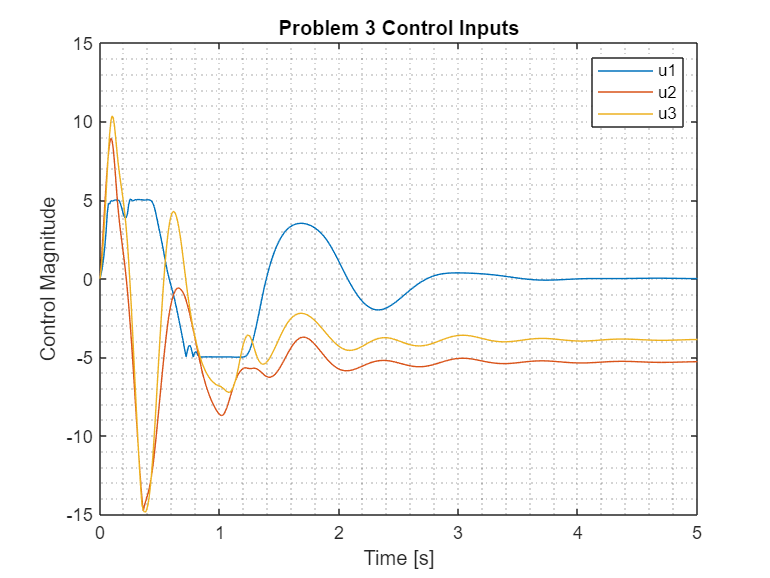

figure
plot(time,U)
xlabel('Time [s]')
ylabel('Control Magnitude')
grid minor
legend('u1','u2','u3')
title('Problem 3 Control Inputs')

## Problem 4 - Constrained Augmented MPC with Observer

% Check Observability
ob     = obsv(A,C);

if rank(ob) == length(A)
    disp('The pair (A,C) is observable')
end

The pair (A,C) is observable


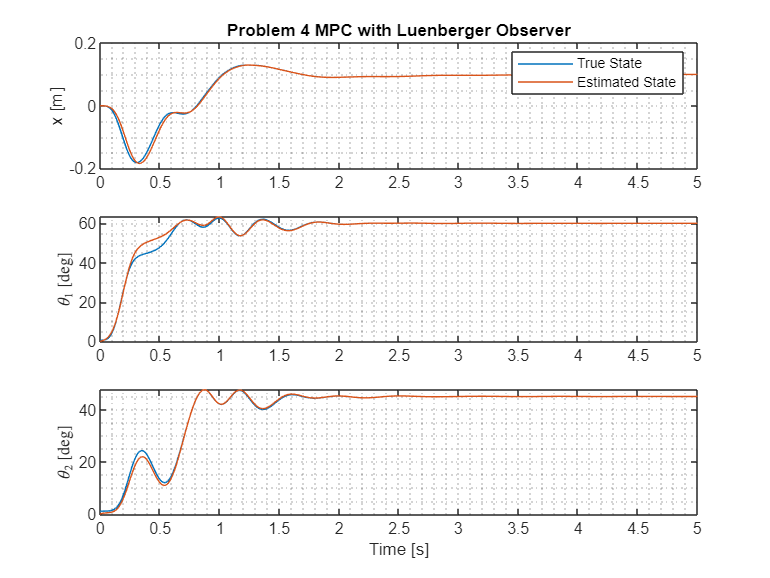

% Desired Observer Poles
s_obs       = linspace(-8,-10,6);

% Observer Gain
L           = place(A',C',s_obs)';

% Observer IC
xtilde0     = zeros(6,1);

% Initialize Output and Input matrices
Y           = zeros(p,length(time));
U           = zeros(m,length(time));
X           = zeros(n,length(time));
Xtilde      = X;
Y(:,1)      = C*x0;
X(:,1)      = x0;

dU          = zeros(m*Np,1);
mu          = zeros(length(Dg),1);

% Simulate with Combined MPC Controller Observer Compensator  
for i = 1:length(time)-1

    % Plant Dynamics
    [~, X_out]  = ode45(@(t,x) ObserverDIPC(t, x, U(:,i), m1, m2, M, L1, L2, g,...
                xe, ue, L, A, B, C, D),[0 h],[X(:,i),Xtilde(:,i)], options);

    % Pull out states, estimates, and outputs
    X(:,i+1)    = X_out(end,1:6)';
    Xtilde(:,i+1) = X_out(end,7:12)';
    Y(:,i+1)    = C*X(1:6,i+1);

    % Augmented state vector using estimates - [delta_xtilde,y]
    xa          = [Xtilde(:,i+1) - Xtilde(:,i); Y(:,i+1)];

    % Optimizer
    for j = 1:250

        % Cost Function Gradient
        grad_J  = -Z'*Q*(rp - W*xa -Z*dU) + R*dU;

        % Constraint Function
        gc       = Dg*dU - [-Umin + U(:,i); Umax - U(:,i); -Ymin + W*xa; Ymax - W*xa];

        % 1st Order Lagrangian Algorithim
        dU      = dU - alpha*(grad_J + Dg'*mu);
        mu      = max(mu + beta*gc,0);
    end

    % Control Action
    U(:,i+1)    = U(:,i) + dU(1:3);
end

figure
subplot(311)
plot(time,X(1,:),time, Xtilde(1,:))
title('Problem 4 MPC with Luenberger Observer')
legend('True State','Estimated State')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi,time, Xtilde(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi,time, Xtilde(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

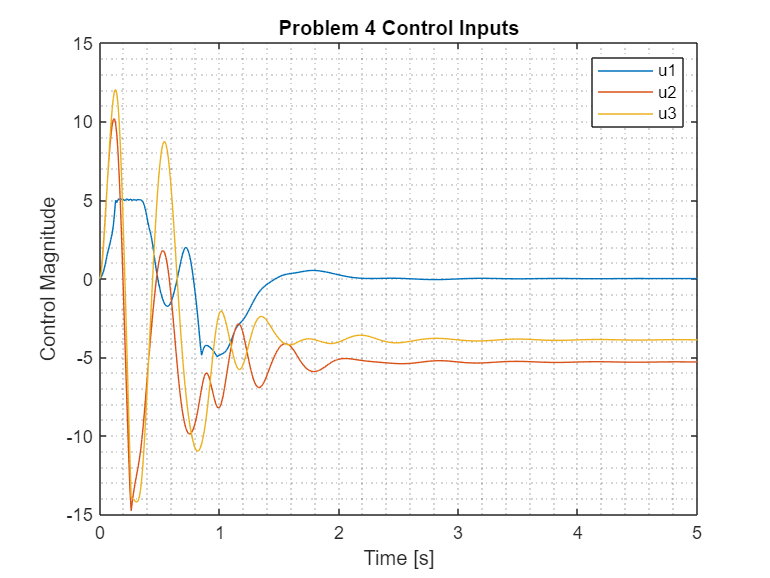

figure
plot(time,U)
xlabel('Time [s]')
ylabel('Control Magnitude')
grid minor
legend('u1','u2','u3')
title('Problem 4 Control Inputs')

% states for simulink animation
aug_sim_states = X(1:3,:);

## Problem 5 - Unconstrained Non-Augmented MPC

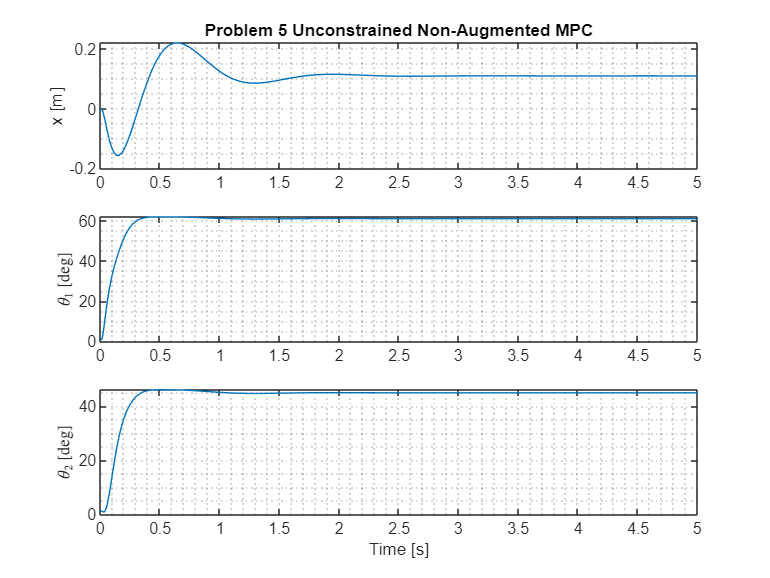

% Set New Prediction Horizon
Np         = 25;

% Redefine Reference Vector
rp         = kron(ones(Np,1),C*xe);

% Initialize Unaugmented W
[row, col] = size(C*phi);
W          = zeros(Np*row,col);
count      = 1;
i          = 1;

% Compute Unaugmented W
while count <= Np
    W(i:i+2,:) = C*phi^count;
    count      = count + 1;
    i          = i + 3;
end

% Compute Unaugmented Z
Z           = zeros(Np*p, Np*m);
Z(1:p,1:m)  = C*gamma;
temp        = C*gamma;

for i = 1:Np-1
    temp = [C*phi^i*gamma temp];
    Z(i*p+1:(i+1)*p,1:size(temp,2)) = temp;
end

% Initialize Output and Input matrices
U           = zeros(m,length(time));
X           = zeros(n,length(time));

X(:,1)      = x0;

% Weighting Matrices
Q           = 10*eye(Np*p);     % State Weight
R           = .001*eye(Np*m);    % Input Weight

% Simulate with Unconstrained Non-Augmented MPC Controller    
for i = 1:length(time)-1

    % Plant Dynamics
    [~, X_out]  = ode45(@(t,x) DIPC(t, x, U(:,i), m1, m2, M, L1, L2, g),[0 h],X(:,i), options);
    X(:,i+1)    = X_out(end,:)';

    % Control Action
    U_new       = inv(R + Z'*Q*Z)*Z'*Q*(rp - W*X(:,i+1));
    U(:,i+1)    = U_new(1:3);
end

figure
subplot(311)
plot(time,X(1,:))
title('Problem 5 Unconstrained Non-Augmented MPC')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

## Problem 6 - Constrained Non-Augmented MPC

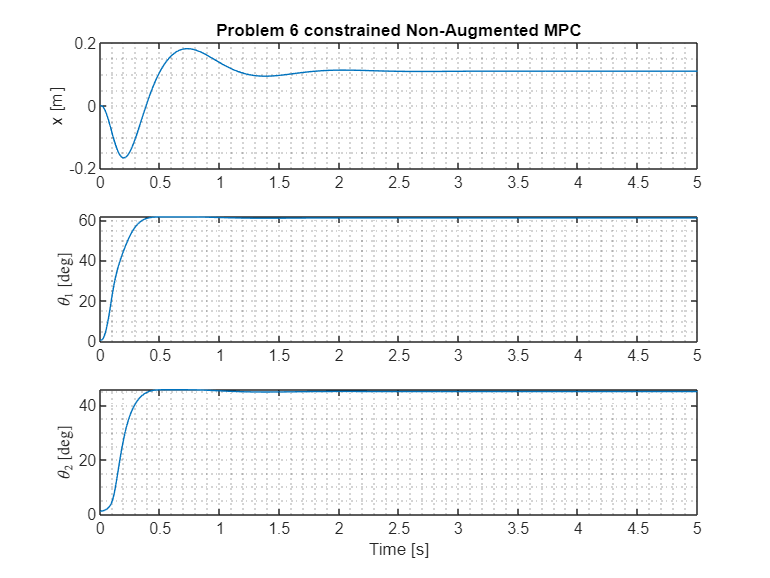

% Ouput Constraints
Ymax        = kron(ones(Np,1),[.2 deg2rad(70), deg2rad(55)]');
Ymin        = -Ymax;

% Input Constraints: Constrain magnitude of U
Umax        = kron(ones(Np,1),[20 20 20]');
Umin        = -Umax;

% Gradient of constraints
Dg          = [-eye(m*Np); eye(m*Np);-Z;Z];

% Initialize Output and Input matrices
U           = zeros(m,length(time));
X           = zeros(n,length(time));
X(:,1)      = x0;
dU          = zeros(m*Np,1);

% Optimization fmincon Options 
opts        = optimoptions('fmincon','MaxIterations',5000,'MaxFunctionEvaluations',1e4,'Display','none');

% Simulate with Constrained Non-Augmented MPC Controller    
for i = 1:length(time)-1
                
    % Plant Dynamics
    [~, X_out]  = ode45(@(t,x) DIPC(t, x, U(:,i), m1, m2, M, L1, L2, g),[0 h],X(:,i), options);
    X(:,i+1)    = X_out(end,:)';

    % Cost FUnction to Optimize
    J = @(U) 1/2*(rp - W*X(:,i+1) - Z*U)'*Q*(rp - W*X(:,i+1) - Z*U) + 1/2*U'*R*U;

    % Optimal Control Sequence
    dU = fmincon(J,dU,Dg,[-Umin;Umax;-Ymin + W*X(:,i+1); Ymax - W*X(:,i+1)],[],[],[],[],[],opts);

    % Control Action
    U(:,i+1)    = dU(1:3);
end

figure
subplot(311)
plot(time,X(1,:))
title('Problem 6 constrained Non-Augmented MPC')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

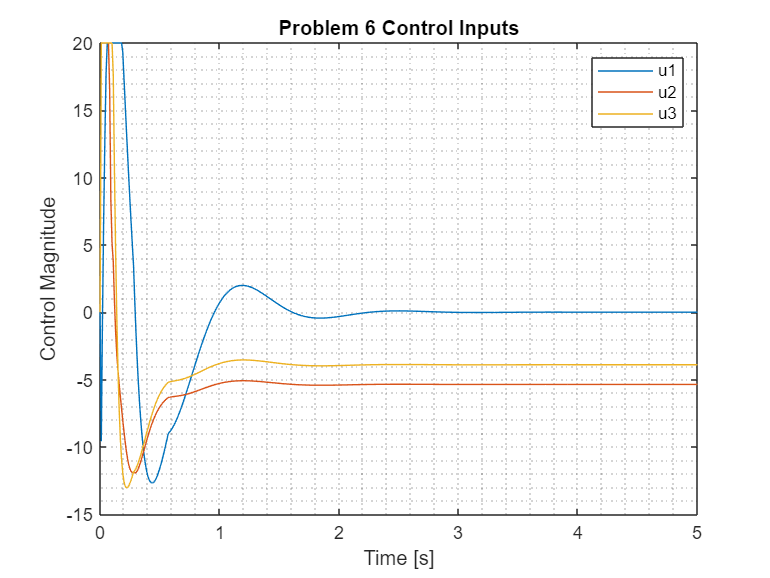

figure
plot(time,U)
xlabel('Time [s]')
ylabel('Control Magnitude')
grid minor
legend('u1','u2','u3')
title('Problem 6 Control Inputs')

## Problem 7 - Constrained Non-Augmented MPC with Observer

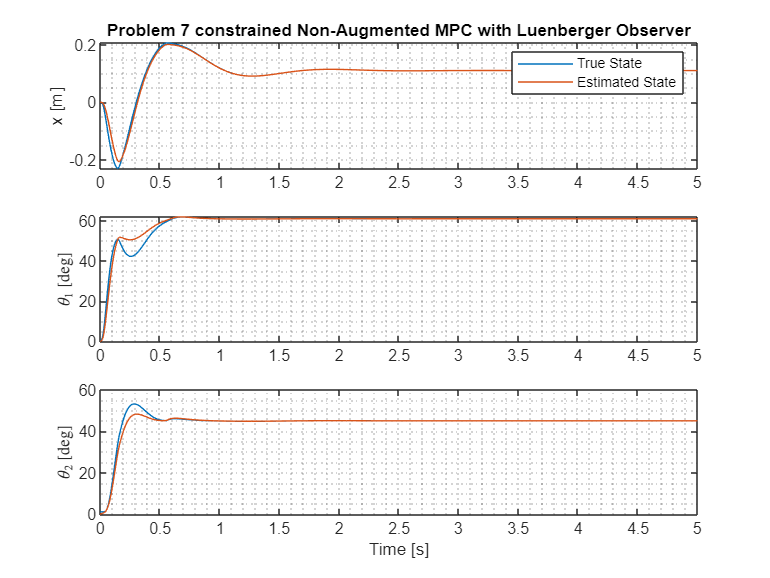

% Observer IC
xtilde0     = zeros(n,1);

% Initialize  matrices
U           = zeros(m,length(time));
X           = zeros(n,length(time));
Xtilde      = X;
X(:,1)      = x0;
dU          = zeros(m*Np,1);

% Input Constraints: Constrain magnitude of U
Umax        = kron(ones(Np,1),[75 75 75]');
Umin        = -Umax;

Ymax        = kron(ones(Np,1),[.2 deg2rad(65), deg2rad(50)]');
Ymin        = -Ymax;

% Simulate with Combined MPC Controller Observer Compensator  
for i = 1:length(time)-1

    % Plant Dynamics
    [~, X_out]      = ode45(@(t,x) ObserverDIPC(t, x, U(:,i), m1, m2, M, L1, L2, g,...
                      xe, ue, L, A, B, C, D),[0 h],[X(:,i),Xtilde(:,i)], options);

    % Pull out states and estimates
    X(:,i+1)        = X_out(end,1:6)';
    Xtilde(:,i+1)   = X_out(end,7:12)';

    % Optimization
    % Cost Function to minimize
    J  = @(U) 1/2*(rp - W*Xtilde(:,i+1) - Z*U)'*Q*(rp - W*Xtilde(:,i+1) - Z*U) + 1/2*U'*R*U;
   
    % Optimal Control Sequence
    dU = fmincon(J,dU,Dg,[-Umin;Umax;-Ymin + W*Xtilde(:,i+1); Ymax - W*Xtilde(:,i+1)],[],[],[],[],[],opts);

    % Control Action
    U(:,i+1)    = dU(1:3);
end

figure
subplot(311)
plot(time,X(1,:),time, Xtilde(1,:))
title('Problem 7 constrained Non-Augmented MPC with Luenberger Observer')
legend('True State','Estimated State')
grid minor
ylabel('x [m]')
subplot(312)
plot(time,X(2,:)*180/pi,time, Xtilde(2,:)*180/pi)
grid minor
ylabel('$\theta_1$ [deg]','Interpreter','latex')
subplot(313)
plot(time,X(3,:)*180/pi,time, Xtilde(3,:)*180/pi)
grid minor
ylabel('$\theta_2$ [deg]','Interpreter','latex')
xlabel('Time [s]')

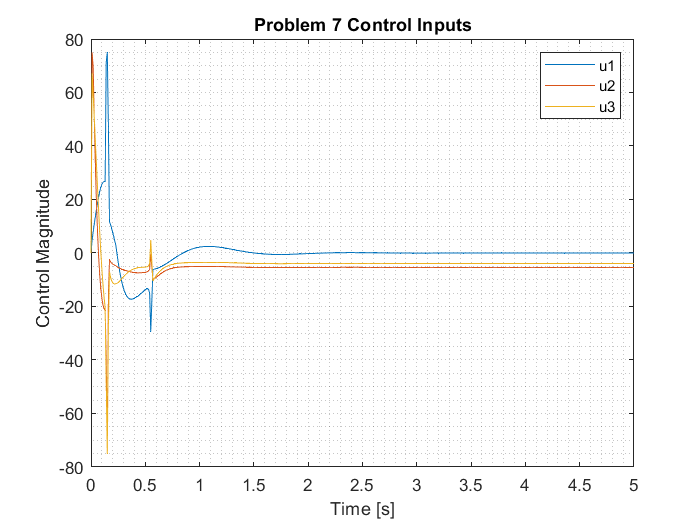

figure
plot(time,U)
xlabel('Time [s]')
ylabel('Control Magnitude')
grid minor
legend('u1','u2','u3')
title('Problem 7 Control Inputs')

% States for Simulink Model
nonaug_sim_states = X(1:3,:);

## Functions

function xdot = DIPC(t, x, u, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
u1          = u(1,1);
u2          = u(2,1);
u3          = u(3,1);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end

% 
function xdot = ObserverDIPC(t, x, u, m1, m2, M, L1, L2, g, xe, ue, L, A, B, C, D)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
x1_tilde    = x(7,1);  % x1_tilde - estimate of x
x2_tilde    = x(8,1);  % x2_tilde - estimate of theta_1
x3_tilde    = x(9,1);  % x3_tilde - estimate of theta_2
x4_tilde    = x(10,1); % x4_tilde - estimate of xdot
x5_tilde    = x(11,1); % x5_tilde - estimate of theta_1_dot
x6_tilde    = x(12,1); % x6_tilde - estimate of theta_2_dot

x_tilde     = [x1_tilde;x2_tilde;x3_tilde;x4_tilde;x5_tilde;x6_tilde];

% Estimated state pertubation: z = delta_xtilde
z           = x_tilde - xe;

% Inputs
u1          = u(1,1);
u2          = u(2,1);
u3          = u(3,1);

% Pertubation Input
del_u       = u(:,1) - ue;

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot(1:6,1) = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

% Output vector - x, theta_1, theta_2
y           = [x1;x2;x3];

% Equilibrium Output
ye          = C*xe;

% Output pertubation vector
del_y       = y - ye;

% Observer Dynamics
del_y_tilde = C*z + D*del_u;
zdot        = A*z + B*del_u + L*(del_y - del_y_tilde);

xdot(7:12,1)= zdot;

end